# Laboratorium 9

### Symulacja zbiornika ze stałym wypływem i grzaniem

Janusz Pawlicki

## 1. Wstęp

### 1.1 Cel ćwiczenia

Celem ćwiczenia jest zamodelowanie zbiornika ze stałym wypływem i grzaniem cieczy. Symulacja polega na numerycznym rozwiązywaniu równań różniczkowych opisujących model zbiornika metodą Eulera w środowisku programistycznym Matlab.

### 1.2 Model

Model zbiornika ze stałym dopływem i wypływem oraz grzaniem, z założeniem idealnego mieszania, jest opisany równaniami różniczkowymi wyprowadzonymi na podstawie zasady zachowania masy:

i z zasady zavhowania energii:

  

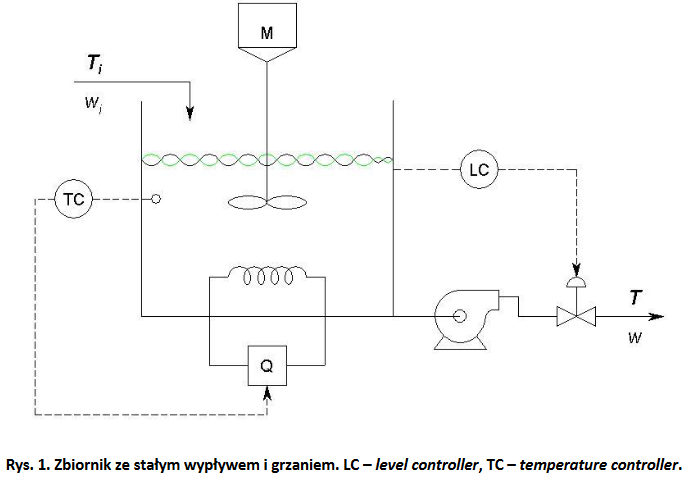

### 1.3 Symulacja

Symulacja modelu polega na rozwiązywaniu równań różniczkowych (1) i (2) w pętli „czasu rzeczywistego” metodą Eulera.

Wychodząc z definicji pochodnej mamy:

więc:

                                               

W metodzie Eulera (różniczkowanie w przód) równanie różniczkowe rozwiązuje się rekurencyjnie:

gdzie h jest okresem próbkowania.

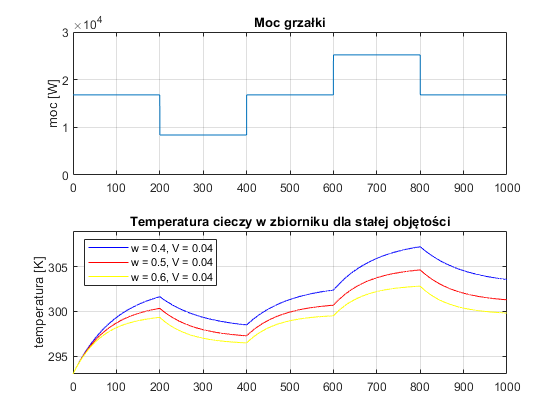

% Dane ------------%
N = 10000;           % liczba próbek
h = 0.1;             % okres próbkowania – 10 próbek to jedna sekunda
Qmax = 25000;        % moc maksymalna grzałki

w_ustalone = 0.4;    % przepływ w stanie ustalonym
w_ustalone2 = 0.5;
w_ustalone3 = 0.6;

Ti = 293;            % temperatura cieczy wlotowe
T_ustalone = 303;    % temperatura cieczy wylotowej w stanie ustalonym

V_ustalone = 0.04;   % objętość w stanie ustalonym
V_ustalone2 = 0.06;
V_ustalone3 = 0.08;

C = 4200;            % ciepło właściwe wody
ro = 1000;           % gęstość wody
%--------------------%
Q_ust = (T_ustalone-Ti)*w_ustalone*C;

t=(0:N-1)*h;

V(1) = V_ustalone;
V2(1) = V_ustalone2;
V3(1) = V_ustalone3;

T1(1) = Ti;
T2(1) = Ti;
T3(1) = Ti;
T4(1) = Ti;
T5(1) = Ti;
T6(1) = Ti;

t(1) = 1;
for k = 1:N-1
    t(k+1) = k+1;
    V(k+1) = V(k);
    X = ones(1,floor(N/5));
    Q = [Q_ust*X, 0.5*Q_ust*X, Q_ust*X, 1.5*Q_ust*X, Q_ust*X];
    T1(k+1) = T1(k) + h*(w_ustalone*(Ti-T1(k))+(Q(k)/C))/(V_ustalone*ro);
    T2(k+1) = T2(k) + h*(w_ustalone2*(Ti-T2(k))+(Q(k)/C))/(V_ustalone*ro);
    T3(k+1) = T3(k) + h*(w_ustalone3*(Ti-T3(k))+(Q(k)/C))/(V_ustalone*ro);
    T4(k+1) = T4(k) + h*(w_ustalone*(Ti-T4(k))+(Q(k)/C))/(V_ustalone*ro);
    T5(k+1) = T5(k) + h*(w_ustalone*(Ti-T5(k))+(Q(k)/C))/(V_ustalone2*ro);
    T6(k+1) = T6(k) + h*(w_ustalone*(Ti-T6(k))+(Q(k)/C))/(V_ustalone3*ro);
end

figure;
subplot(2,1,1)
plot(t/10,Q)
title('Moc grzałki')
ylabel('moc [W]')
grid on;
axis([0 1000 0 30000])
subplot(2,1,2)
plot(t/10,T1,'b',t/10,T2,'r',t/10,T3,'y')
axis([0 1000 293 309])
title('Temperatura cieczy w zbiorniku dla stałej objętości')
legend('w = 0.4, V = 0.04','w = 0.5, V = 0.04','w = 0.6, V = 0.04','Location','northwest')
ylabel('temperatura [K]')
grid on;

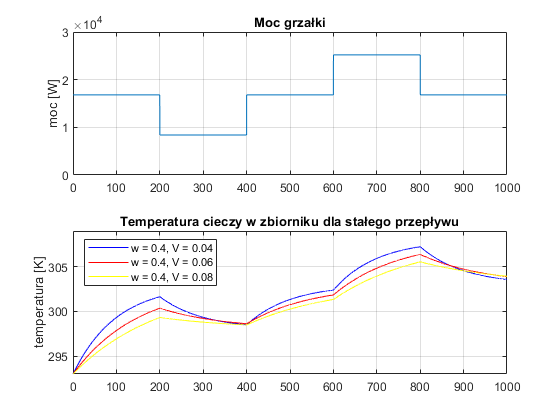




figure;
subplot(2,1,1)
plot(t/10,Q)
title('Moc grzałki')
ylabel('moc [W]')
grid on;
axis([0 1000 0 30000])
subplot(2,1,2)
plot(t/10,T4,'b',t/10,T5,'r',t/10,T6,'y')
axis([0 1000 293 309])
title('Temperatura cieczy w zbiorniku dla stałego przepływu')
legend('w = 0.4, V = 0.04','w = 0.4, V = 0.06','w = 0.4, V = 0.08','Location','northwest')
ylabel('temperatura [K]')
grid on;